modulePath = 'C:/Users/Asus/Studia/Projekt IPS/dane - semestr 5/MATLAB_project/python_modules';
insert(py.sys.path, int32(0), modulePath);
load("C:\Users\Asus\Studia\Projekt IPS\dane - semestr 5\MATLAB_project\ab_diff_zestaw.mat")

function SARIMA_A514 = model_A5(A5)
    A51 = A5(:,1);
    SARIMA_A514 = arima('Constant',NaN,'ARLags',1:2,'D',0,'MALags',[1,2],'SARLags',[21,42],'Seasonality',21,'SMALags',[21,42],'Distribution','Gaussian');
    SARIMA_A514 = estimate(SARIMA_A514,A51,'Display','off');
end

function results_py = model_HoltWinters(y_train, y_test, step_length, season_period)
    py_model = py.importlib.import_module("HoltWintersModule");
    results_py = py_model.forecast_holt_winters(...
        y_train,...
        y_test,...
        step_length,...
        season_period ...
        ).double;
end

% Wzór R2_1 (Standardowy Współczynnik Determinacji)
R2_classic = @(y_true, y_pred) 1 - (sum((y_true(:) - y_pred(:)).^2) / sum((y_true(:) - mean(y_true(:))).^2));

% Wzór R2_2 (Frakcja Wyjaśnionej Wariancji)
R2_alt = @(y_true, y_pred) sum((y_pred(:) - mean(y_true(:))).^2) / sum((y_true(:) - mean(y_true(:))).^2);

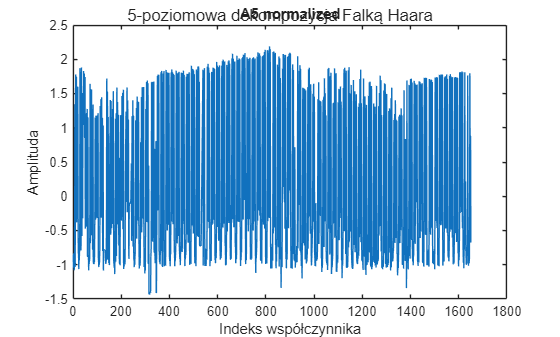

% ZBIÓR TRENINGOWY
[c, l] = wavedec(ab_diff_train_norm, 5, 'Haar');

% Pobierz współczynniki aproksymacji A i szczegółów D
A1 = appcoef(c, l, 'haar', 1);
A5 = appcoef(c, l, 'haar', 5);

D5 = detcoef(c, l, 5);
D4 = detcoef(c, l, 4);
D3 = detcoef(c, l, 3);
D2 = detcoef(c, l, 2);
D1 = detcoef(c, l, 1);

% normalizacja współczynników
[D2_norm, center_D2, scale_D2] = normalize(D2);
[A5_norm, center_A5, scale_A5] = normalize(A5);

% 2. RYSOWANIE WYKRESÓW
plot(A5_norm);
title('A5 normalized');
xlabel('Indeks współczynnika');
ylabel('Amplituda');
sgtitle('5-poziomowa dekompozycja Falką Haara');


% TEST
[c_test, l_test] = wavedec(ab_diff_test_norm, 5, 'Haar');

% Pobierz współczynniki aproksymacji (Trend) z poziomu 5
A1_test = appcoef(c_test, l_test, 'haar', 1);
A5_test = appcoef(c_test, l_test, 'haar', 5);

D5_test = detcoef(c_test, l_test, 5);
D4_test = detcoef(c_test, l_test, 4);
D3_test = detcoef(c_test, l_test, 3);
D2_test = detcoef(c_test, l_test, 2);
D1_test = detcoef(c_test, l_test, 1);

% Normalizacja współczynników testowych
D2_test_norm = (D2_test - center_D2) ./ scale_D2;
A5_test_norm = (A5_test - center_A5) ./ scale_A5;

dlugosc_testu_oryginalna = 2880; % Horyzont w oryginalnej dziedzinie czasu (2880 próbek)

step_length = 4;
step_length_A5 = ceil(step_length / 32);
step_length_D2 = ceil(step_length / 4);

dlugosc_testu_A5 = ceil(dlugosc_testu_oryginalna / 32);
dlugosc_testu_D2 = ceil(dlugosc_testu_oryginalna / 4);

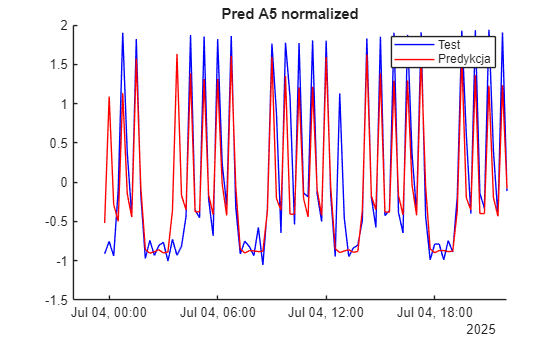

% Przewidywania A5 - model CHRONOS
Mdl_A5 = model_A5(A5_norm);
A5_pred_norm = forecast(Mdl_A5, dlugosc_testu_A5, 'Y0', A5_norm);


% Narysuj wykres
figure;
hold on;
plot(ab_diff_test.Time(1:dlugosc_testu_A5), A5_test_norm(1:dlugosc_testu_A5), 'Color','blue', 'DisplayName','Test');
plot(ab_diff_test.Time(1:dlugosc_testu_A5), A5_pred_norm, 'Color','red','DisplayName','Predykcja');
title('Pred A5 normalized');
legend;

% Przewidywania D2 - model CHRONOS
D2_pred_norm = model_HoltWinters(D2_norm, D2_test_norm(1:dlugosc_testu_D2), step_length_D2, 24)

Rozpoczynanie prognozy (Refitting Expanding Window)...
Rozmiar testowy: 720, Krok: 1, Pętle: 720
  Pętla 1/720 (Rozmiar danych tren.: 13200)...
  Pętla 2/720 (Rozmiar danych tren.: 13201)...
  Pętla 3/720 (Rozmiar danych tren.: 13202)...
  Pętla 4/720 (Rozmiar danych tren.: 13203)...
  Pętla 5/720 (Rozmiar danych tren.: 13204)...
  Pętla 6/720 (Rozmiar danych tren.: 13205)...
  Pętla 7/720 (Rozmiar danych tren.: 13206)...
  Pętla 8/720 (Rozmiar danych tren.: 13207)...
  Pętla 9/720 (Rozmiar danych tren.: 13208)...
  Pętla 10/720 (Rozmiar danych tren.: 13209)...
  Pętla 11/720 (Rozmiar danych tren.: 13210)...
  Pętla 12/720 (Rozmiar danych tren.: 13211)...
  Pętla 13/720 (Rozmiar danych tren.: 13212)...
  Pętla 14/720 (Rozmiar danych tren.: 13213)...
  Pętla 15/720 (Rozmiar danych tren.: 13214)...
  Pętla 16/720 (Rozmiar danych tren.: 13215)...
  Pętla 17/720 (Rozmiar danych tren.: 13216)...
  Pętla 18/720 (Rozmiar danych tren.: 13217)...
  Pętla 19/720 (Rozmiar danych tren.: 13218)...


D2_pred_norm =     0.0079   -0.0142   -0.0037   -0.0997   -0.1762   -0.5004   -0.4825   -0.1837   -0.0522   -0.0314    0.0577    0.0010   -0.0315   -0.0219    0.2352    0.1679    0.2491    0.2148    0.2637    0.1933    0.0816    0.0165   -0.0371    0.1464    0.0079   -0.0136   -0.0037   -0.1005   -0.1684   -0.4995   -0.4816   -0.1839   -0.2139    0.0114    0.0576    0.0010   -0.0314   -0.0433    0.1338    0.2573    0.0416    0.1721    0.1125    0.3220    0.1679    0.0164   -0.0370    0.0026    0.0144   -0.0136


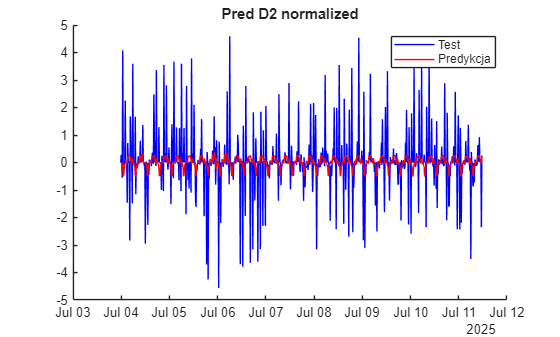


% Narysuj wykres
figure;
hold on;
plot(ab_diff_test.Time(1:dlugosc_testu_D2), D2_test_norm(1:dlugosc_testu_D2), 'Color','blue', 'DisplayName','Test');
plot(ab_diff_test.Time(1:dlugosc_testu_D2), D2_pred_norm, 'Color','red','DisplayName','Predykcja');
title('Pred D2 normalized');
legend;

% DENORMALIZACJA
% Odwracamy proces: x = y * scale + center
A5_pred = (A5_pred_norm .* scale_A5) + center_A5;
D2_pred = (D2_pred_norm .* scale_D2) + center_D2;

% Obliczamy długości wektorów dla brakujących poziomów (dla zadanego horyzontu)
len_A5 = length(A5_pred);
len_D5 = len_A5;      % Z własności Haara
len_D4 = len_A5 * 2;
len_D3 = len_A5 * 4;
len_D2 = len_A5 * 8;
len_D1 = len_A5 * 16;

% Budowa wektora c_pred
c_pred = [
    A5_pred;             % Predykcja CHRONOS
    zeros(len_D5, 1);     % D5 - zerujemy
    zeros(len_D4, 1);     % D4 - zerujemy
    zeros(len_D3, 1);     % D3 - zerujemy
    D2_pred';             % Predykcja CHRONOS
    zeros(len_D1, 1);     % D1 - zerujemy
];

total_len = length(c_pred);
l_pred = [
    length(A5_pred);
    length(A5_pred);      % D5
    length(A5_pred)*2;    % D4
    length(A5_pred)*4;    % D3
    length(A5_pred)*8;    % D2
    length(A5_pred)*16;   % D1
    length(A5_pred)*32    % Całkowita długość sygnału
];

final_prediction = waverec(c_pred, l_pred, 'haar');      % podejście: A5 i D2 CHRONOS
y_test = ab_diff_test_norm(1:length(final_prediction))';

mae_score = mae(y_test, final_prediction')

mae_score = 0.2085

mape_score = mape(y_test, final_prediction')

mape_score = 70.8215

rmse_score = rmse(y_test, final_prediction')

rmse_score = 0.2573

r2_classic = R2_classic(y_test, final_prediction')

r2_classic = 0.4475

r2_alt = R2_alt(y_test, final_prediction')

r2_alt = 0.4165

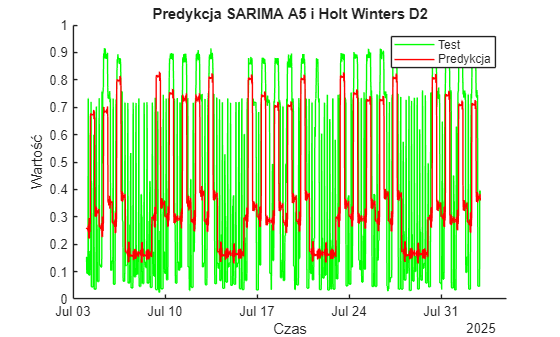


figure;
hold on;
plot(ab_diff_test.Time(1:dlugosc_testu_oryginalna), ab_diff_test_norm(1:dlugosc_testu_oryginalna), 'Color','green','DisplayName','Test');
plot(ab_diff_test.Time(1:dlugosc_testu_oryginalna), final_prediction, 'Color','red','DisplayName','Predykcja');
xlabel('Czas');
ylabel('Wartość');
title("Predykcja SARIMA A5 i Holt Winters D2")
legend;

% Tworzenie tabeli z czasem, danymi i predykcją
T_z_czasem = table(ab_diff_test.Time(1:dlugosc_testu_oryginalna), ...
                   ab_diff_test_norm(1:dlugosc_testu_oryginalna), ...
                   final_prediction(1:dlugosc_testu_oryginalna), ...
    'VariableNames', {'Czas', 'Dane_Prawdziwe', 'Predykcja'});

writetable(T_z_czasem, "pred_ab_A5_D2_SARIMA_HW_month_"+ num2str(step_length)+".xlsx");